close all; clear all; clc

% parameters
M=3; m1=1; m2=1;
L1=1; L2=1; g=9.81;

% % state space model
% A = [0 1 0 0; 0 0 m*g/L 0; 0 0 0 1; 0 0 (M+m)*g/(M*L) 0];
% B = [0; 1/M; 0; 1/(M*L)];
% 
% % LQR
% Q = diag([10,1,50,10])
% R = 0.001
% K = lqr(A,B,Q,R);

% simulation
tspan = 0:0.05:5;
%wr = [-3; 0; 0; 0]; % reference position
%u=@(y)-K*(y - wr); % control law

y0 = [0 0.5 deg2rad(0) 0 deg2rad(10) 0]; % initial state
[t,y] = ode45(@(t,y)simpend(y,M,m1,m2,L1,L2,g,0),tspan,y0);

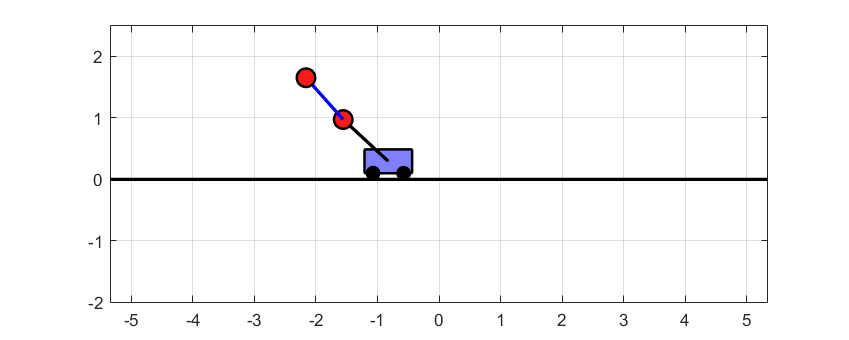

% play the animation
for k=1:length(t)
    drawpend(y(k,:),m1,M,L1,L2);
end

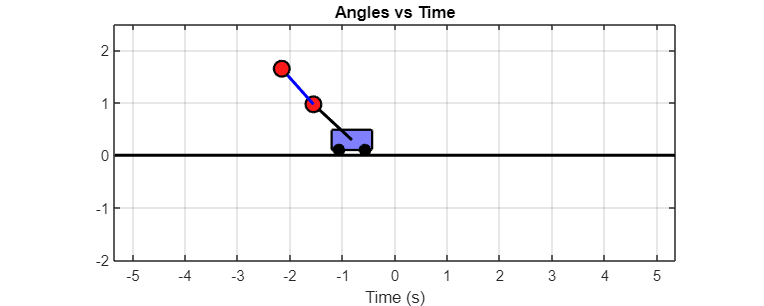

title("Angles vs Time")
xlabel('Time (s)')
ylabel('')

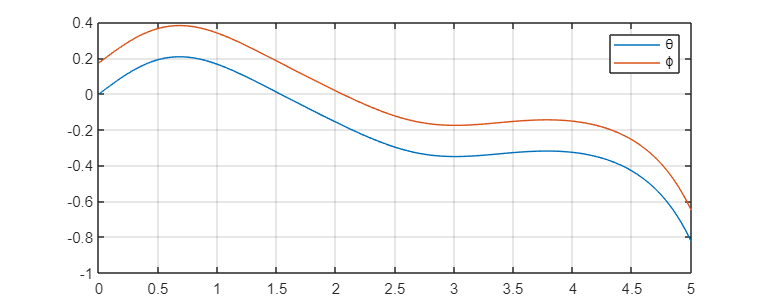

plot(t,y(:,3)); hold on
plot(t,y(:,5))
legend('\theta','\phi')
grid on